% -- SPECTRAL PREPROCESSING WORKSTATION -----------------------------------
% Written by Cristian Ciobanu
%
% EDITED^2
%
% This is a workstation for preprocessing and analyzing Raman spectra.

close all;
clear;
clc;
format long;

% -- GLOBAL INTERMEDIATE PREPROCESSED SPECTRA -----------------------------
% global csr sgf MSC SNV bgr bge hqt nrm avg hqr mdn craynum 

% -- GLOBAL PREPROCESSING SETTINGS ----------------------------------------
global avgNum sgfOrder sgfWindow snipOrder snipWindow
global threshold1 threshold2 remType range NISTspectrum

% cosmic ray removal settings
threshold1 = 6;
threshold2 = 1;
range = 1;
remType = 1;

% smoothing and averaging settings
sgfOrder = 2;
sgfWindow = 11;
avgNum = 15;
snipWindow = 111;
snipOrder = 2;

% -- PREPROCESSING OPTIONS ------------------------------- 6,1,11,10,8,2,5,6,7
% 1 - Cosmic Ray Removal         2 - Savitzky-Golay Smoothing
% 3 - MSC Correction             4 - SNV Correction
% 5 - Background Removal         6 - Outlier Removal
% 7 - Normalization              8 - Shuffle Averaging
% 9 - Median                     10 - Shift correction
% 11 - NIST correction

global standardSamples std_int shifts corr_shifts crnt info

% Reading in Silicon and Polystyrene data from separate collection dates

data_path = "/Users/haydnflemming/Desktop/LLAMPE - Research Project/Data/2024-07-25/";

% Determine the number of metadata rows to skip
numMetadataRows = 21; % Adjust this based on your inspection

% well 1 data

file_name = "Blood_Plasma1(40x,495mW,Well1)_2000_30_2024-07-25-14.05.15.270.csv";
file_path = data_path+file_name;
blood_1_1 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma2(40x,495mW,Well1)_2000_30_2024-07-25-14.06.46.857.csv";
file_path = strcat(data_path,file_name);
blood_2_1 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma3(40x,495mW,Well1)_2000_30_2024-07-25-14.08.19.973.csv";
file_path = strcat(data_path,file_name);
blood_3_1 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma4(40x,495mW,Well1)_2000_30_2024-07-25-14.09.54.200.csv";
file_path = strcat(data_path,file_name);
blood_4_1 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma5(40x,495mW,Well1)_2000_30_2024-07-25-14.11.27.703.csv";
file_path = strcat(data_path,file_name);
blood_5_1 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma6(40x,495mW,Well1)_2000_30_2024-07-25-14.13.11.530.csv";
file_path = strcat(data_path,file_name);
blood_6_1 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma7(40x,495mW,Well1)_2000_30_2024-07-25-14.14.49.133.csv";
file_path = strcat(data_path,file_name);
blood_7_1 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma8(40x,495mW,Well1)_2000_30_2024-07-25-14.16.26.297.csv";
file_path = strcat(data_path,file_name);
blood_8_1 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma9(40x,495mW,Well1)_2000_30_2024-07-25-14.18.03.237.csv";
file_path = strcat(data_path,file_name);
blood_9_1 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma10(40x,495mW,Well1)_2000_30_2024-07-25-14.19.38.440.csv";
file_path = strcat(data_path,file_name);
blood_10_1 = csvread(file_path, numMetadataRows, 0);

% well 2 data

file_name = "Blood_Plasma1(40x,495mW,Well2)_2000_30_2024-07-25-14.24.59.957.csv";
file_path = data_path+file_name;
blood_1_2 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma2(40x,495mW,Well2)_2000_30_2024-07-25-14.26.45.030.csv";
file_path = strcat(data_path,file_name);
blood_2_2 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma3(40x,495mW,Well2)_2000_30_2024-07-25-14.28.23.900.csv";
file_path = strcat(data_path,file_name);
blood_3_2 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma4(40x,495mW,Well2)_2000_30_2024-07-25-14.30.12.177.csv";
file_path = strcat(data_path,file_name);
blood_4_2 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma5(40x,495mW,Well2)_2000_30_2024-07-25-14.31.52.960.csv";
file_path = strcat(data_path,file_name);
blood_5_2 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma6(40x,495mW,Well2)_2000_30_2024-07-25-14.33.41.333.csv";
file_path = strcat(data_path,file_name);
blood_6_2 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma7(40x,495mW,Well2)_2000_30_2024-07-25-14.35.14.063.csv";
file_path = strcat(data_path,file_name);
blood_7_2 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma8(40x,495mW,Well2)_2000_30_2024-07-25-14.36.44.690.csv";
file_path = strcat(data_path,file_name);
blood_8_2 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma9(40x,495mW,Well2)_2000_30_2024-07-25-14.38.20.207.csv";
file_path = strcat(data_path,file_name);
blood_9_2 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma10(40x,495mW,Well2)_2000_30_2024-07-25-14.39.51.797.csv";
file_path = strcat(data_path,file_name);
blood_10_2 = csvread(file_path, numMetadataRows, 0);

% well 3 data

file_name = "Blood_Plasma1(40x,495mW,Well3)_2000_30_2024-07-25-14.45.00.530.csv";
file_path = data_path+file_name;
blood_1_3 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma2(40x,495mW,Well3)_2000_30_2024-07-25-14.46.49.117.csv";
file_path = strcat(data_path,file_name);
blood_2_3 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma3(40x,495mW,Well3)_2000_30_2024-07-25-14.48.28.807.csv";
file_path = strcat(data_path,file_name);
blood_3_3 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma4(40x,495mW,Well3)_2000_30_2024-07-25-14.50.08.897.csv";
file_path = strcat(data_path,file_name);
blood_4_3 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma5(40x,495mW,Well3)_2000_30_2024-07-25-14.51.43.910.csv";
file_path = strcat(data_path,file_name);
blood_5_3 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma6(40x,495mW,Well3)_2000_30_2024-07-25-14.53.23.793.csv";
file_path = strcat(data_path,file_name);
blood_6_3 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma7(40x,495mW,Well3)_2000_30_2024-07-25-14.55.05.657.csv";
file_path = strcat(data_path,file_name);
blood_7_3 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma8(40x,495mW,Well3)_2000_30_2024-07-25-14.56.38.537.csv";
file_path = strcat(data_path,file_name);
blood_8_3 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma9(40x,495mW,Well3)_2000_30_2024-07-25-14.58.22.177.csv";
file_path = strcat(data_path,file_name);
blood_9_3 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma10(40x,495mW,Well3)_2000_30_2024-07-25-15.00.05.140.csv";
file_path = strcat(data_path,file_name);
blood_10_3 = csvread(file_path, numMetadataRows, 0);

file_name = "NIST(40x,495mW)_50_250_2024-07-25-13.25.42.187.csv";
file_path = strcat(data_path,file_name);
NISTspectrum = csvread(file_path, numMetadataRows, 0);

file_name = "Polystyrene(40x,495mW)_60_250_2024-07-25-13.35.03.900.csv";
file_path = strcat(data_path,file_name);
poly1 = csvread(file_path, numMetadataRows, 0);
poly = mean(poly1(2:end,:));

file_name = "Silicon(40x,495mW)_50_250_2024-07-25-13.39.18.243.csv";
file_path = strcat(data_path,file_name);
Si1 = csvread(file_path, numMetadataRows, 0);
Si = mean(Si1(2:end,:));

std_int = [poly1(1, :) ; poly ; Si];

% Configuring and plotting unprocessed data

wavenumber = blood_1_3(1,:);

% trimming standard sample data to these WN's
t1 = 500;
t2 = 1800;

wavenumber(:, wavenumber(1, :) <= t1) = [];
wavenumber(:, wavenumber(1, :) >= t2) = [];

blood_1_1(:, blood_1_1(1, :) <= t1) = [];
blood_1_1(:, blood_1_1(1, :) >= t2) = [];
blood_2_1(:, blood_2_1(1, :) <= t1) = [];
blood_2_1(:, blood_2_1(1, :) >= t2) = [];
blood_3_1(:, blood_3_1(1, :) <= t1) = [];
blood_3_1(:, blood_3_1(1, :) >= t2) = [];
blood_4_1(:, blood_4_1(1, :) <= t1) = [];
blood_4_1(:, blood_4_1(1, :) >= t2) = [];
blood_5_1(:, blood_5_1(1, :) <= t1) = [];
blood_5_1(:, blood_5_1(1, :) >= t2) = [];
blood_6_1(:, blood_6_1(1, :) <= t1) = [];
blood_6_1(:, blood_6_1(1, :) >= t2) = [];
blood_7_1(:, blood_7_1(1, :) <= t1) = [];
blood_7_1(:, blood_7_1(1, :) >= t2) = [];
blood_8_1(:, blood_8_1(1, :) <= t1) = [];
blood_8_1(:, blood_8_1(1, :) >= t2) = [];
blood_9_1(:, blood_9_1(1, :) <= t1) = [];
blood_9_1(:, blood_9_1(1, :) >= t2) = [];
blood_10_1(:, blood_10_1(1, :) <= t1) = [];
blood_10_1(:, blood_10_1(1, :) >= t2) = [];

blood_1_2(:, blood_1_2(1, :) <= t1) = [];
blood_1_2(:, blood_1_2(1, :) >= t2) = [];
blood_2_2(:, blood_2_2(1, :) <= t1) = [];
blood_2_2(:, blood_2_2(1, :) >= t2) = [];
blood_3_2(:, blood_3_2(1, :) <= t1) = [];
blood_3_2(:, blood_3_2(1, :) >= t2) = [];
blood_4_2(:, blood_4_2(1, :) <= t1) = [];
blood_4_2(:, blood_4_2(1, :) >= t2) = [];
blood_5_2(:, blood_5_2(1, :) <= t1) = [];
blood_5_2(:, blood_5_2(1, :) >= t2) = [];
blood_6_2(:, blood_6_2(1, :) <= t1) = [];
blood_6_2(:, blood_6_2(1, :) >= t2) = [];
blood_7_2(:, blood_7_2(1, :) <= t1) = [];
blood_7_2(:, blood_7_2(1, :) >= t2) = [];
blood_8_2(:, blood_8_2(1, :) <= t1) = [];
blood_8_2(:, blood_8_2(1, :) >= t2) = [];
blood_9_2(:, blood_9_2(1, :) <= t1) = [];
blood_9_2(:, blood_9_2(1, :) >= t2) = [];
blood_10_2(:, blood_10_2(1, :) <= t1) = [];
blood_10_2(:, blood_10_2(1, :) >= t2) = [];

blood_1_3(:, blood_1_3(1, :) <= t1) = [];
blood_1_3(:, blood_1_3(1, :) >= t2) = [];
blood_2_3(:, blood_2_3(1, :) <= t1) = [];
blood_2_3(:, blood_2_3(1, :) >= t2) = [];
blood_3_3(:, blood_3_3(1, :) <= t1) = [];
blood_3_3(:, blood_3_3(1, :) >= t2) = [];
blood_4_3(:, blood_4_3(1, :) <= t1) = [];
blood_4_3(:, blood_4_3(1, :) >= t2) = [];
blood_5_3(:, blood_5_3(1, :) <= t1) = [];
blood_5_3(:, blood_5_3(1, :) >= t2) = [];
blood_6_3(:, blood_6_3(1, :) <= t1) = [];
blood_6_3(:, blood_6_3(1, :) >= t2) = [];
blood_7_3(:, blood_7_3(1, :) <= t1) = [];
blood_7_3(:, blood_7_3(1, :) >= t2) = [];
blood_8_3(:, blood_8_3(1, :) <= t1) = [];
blood_8_3(:, blood_8_3(1, :) >= t2) = [];
blood_9_3(:, blood_9_3(1, :) <= t1) = [];
blood_9_3(:, blood_9_3(1, :) >= t2) = [];
blood_10_3(:, blood_10_3(1, :) <= t1) = [];
blood_10_3(:, blood_10_3(1, :) >= t2) = [];

shifts = wavenumber;

blood1_1 = blood_1_1(2:end, :);
blood2_1 = blood_2_1(2:end, :);
blood3_1 = blood_3_1(2:end, :);
blood4_1 = blood_4_1(2:end, :);
blood5_1 = blood_5_1(2:end, :);
blood6_1 = blood_6_1(2:end, :);
blood7_1 = blood_7_1(2:end, :);
blood8_1 = blood_8_1(2:end, :);
blood9_1 = blood_9_1(2:end, :);
blood10_1 = blood_10_1(2:end, :);

blood1_2 = blood_1_2(2:end, :);
blood2_2 = blood_2_2(2:end, :);
blood3_2 = blood_3_2(2:end, :);
blood4_2 = blood_4_2(2:end, :);
blood5_2 = blood_5_2(2:end, :);
blood6_2 = blood_6_2(2:end, :);
blood7_2 = blood_7_2(2:end, :);
blood8_2 = blood_8_2(2:end, :);
blood9_2 = blood_9_2(2:end, :);
blood10_2 = blood_10_2(2:end, :);

blood1_3 = blood_1_3(2:end, :);
blood2_3 = blood_2_3(2:end, :);
blood3_3 = blood_3_3(2:end, :);
blood4_3 = blood_4_3(2:end, :);
blood5_3 = blood_5_3(2:end, :);
blood6_3 = blood_6_3(2:end, :);
blood7_3 = blood_7_3(2:end, :);
blood8_3 = blood_8_3(2:end, :);
blood9_3 = blood_9_3(2:end, :);
blood10_3 = blood_10_3(2:end, :);

std_int(:, std_int(1, :) <= t1) = [];
std_int(:, std_int(1, :) >= t2) = [];
std_int(1, :) = [];
standardSamples = ["Polystyrene" ; "Silicon"];

NISTspectrum(:, NISTspectrum(1, :) <= t1) = [];
NISTspectrum(:, NISTspectrum(1, :) >= t2) = [];
NISTspectrum(1, :) = [];

## Blood Plasma Well Trial 2024-07-25, D223 150μL Sample

- Data from each well is shown, including raw data in the first plot from each section, group processed data in the second plot, and individually processed data by trial in the third plot.

- The sample was prepared by removing from the freezer, rocking for 35 minutes, and then rested for 7 minutes in the well slide.

- Samples were pipetted into 3 50μL wells and then covered with a 22mmx22mm No. 1 Cover Glass slip.

- Data was taken using a 40x immersion objective lens by using a dropper bottle to place water on the cover glass slip atop the well slide then immersing the lens in the water drop, then focusing the objective over each well using a motorized XYZ stage.

- In the 'group processed' plots, an array was made combining data from all trials in that well, and then the 'apply' function was used for processing.

- In the 'individual processing' plots, the 'apply' function was used individually on each trial, and then the resulting pre-processed data was then plotted together in a figure.

# Well 1 Data

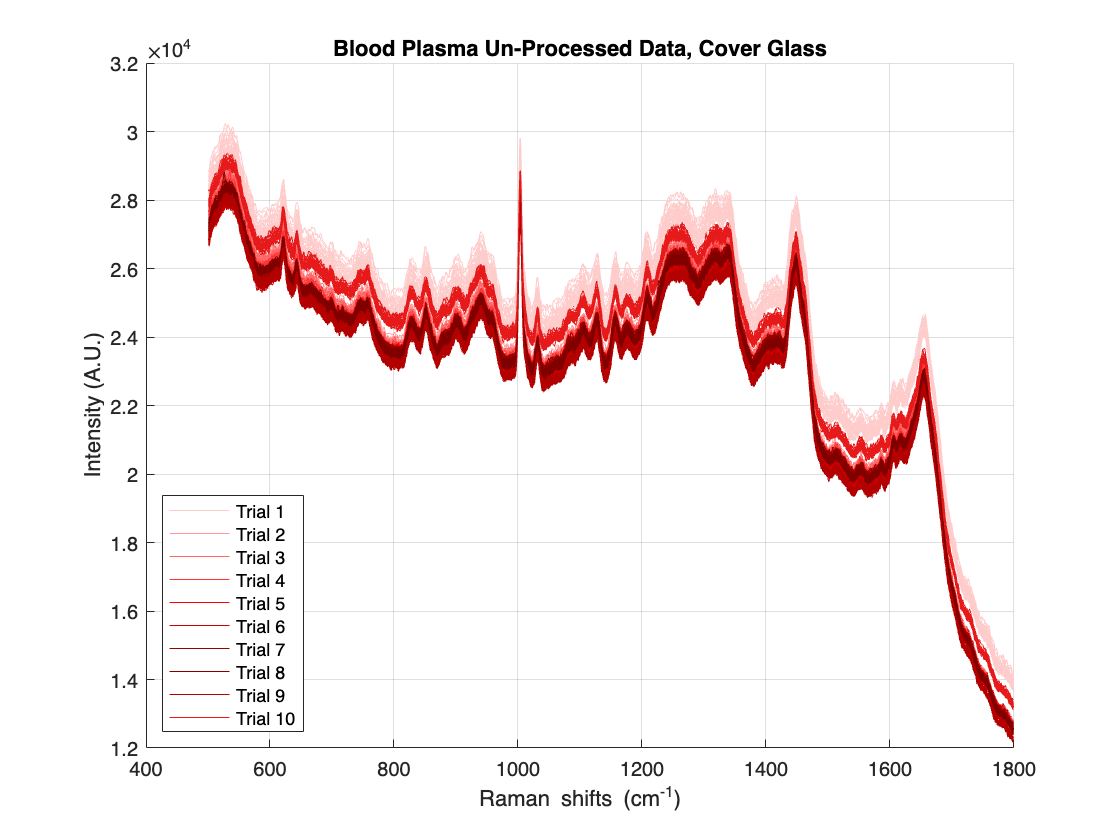

% Plotting unprocessed data

figure;
hold on;
grid on;
plot(wavenumber, blood1_1(1,:), 'Color', [1.00, 0.80, 0.80]); % Light Red
plot(wavenumber, blood2_1(1,:), 'Color', [1.00, 0.60, 0.60]); % Light Coral
plot(wavenumber, blood3_1(1,:), 'Color', [1.00, 0.40, 0.40]); % Salmon
plot(wavenumber, blood4_1(1,:), 'Color', [1.00, 0.20, 0.20]); % Indian Red
plot(wavenumber, blood5_1(1,:), 'Color', [1.00, 0.00, 0.00]); % Red
plot(wavenumber, blood6_1(1,:), 'Color', [0.80, 0.00, 0.00]); % Fire Brick
plot(wavenumber, blood7_1(1,:), 'Color', [0.60, 0.00, 0.00]); % Dark Red
plot(wavenumber, blood8_1(1,:), 'Color', [0.50, 0.00, 0.00]); % Maroon
plot(wavenumber, blood9_1(1,:), 'Color', [0.70, 0.00, 0.00]); % Crimson
plot(wavenumber, blood10_1(1,:), 'Color', [0.90, 0.10, 0.10]); % Light Red
plot(wavenumber, blood1_1(2:end,:), 'Color', [1.00, 0.80, 0.80]); % Light Red
plot(wavenumber, blood2_1(2:end,:), 'Color', [1.00, 0.60, 0.60]); % Light Coral
plot(wavenumber, blood3_1(2:end,:), 'Color', [1.00, 0.40, 0.40]); % Salmon
plot(wavenumber, blood4_1(2:end,:), 'Color', [1.00, 0.20, 0.20]); % Indian Red
plot(wavenumber, blood5_1(2:end,:), 'Color', [1.00, 0.00, 0.00]); % Red
plot(wavenumber, blood6_1(2:end,:), 'Color', [0.80, 0.00, 0.00]); % Fire Brick
plot(wavenumber, blood7_1(2:end,:), 'Color', [0.60, 0.00, 0.00]); % Dark Red
plot(wavenumber, blood8_1(2:end,:), 'Color', [0.50, 0.00, 0.00]); % Maroon
plot(wavenumber, blood9_1(2:end,:), 'Color', [0.70, 0.00, 0.00]); % Crimson
plot(wavenumber, blood10_1(2:end,:), 'Color', [0.90, 0.10, 0.10]); % Light Red
xlabel('Raman shifts (cm^{-1})');
ylabel('Intensity (A.U.)');
title('Blood Plasma Un-Processed Data, Cover Glass');
legend('Trial 1','Trial 2','Trial 3','Trial 4','Trial 5','Trial 6','Trial 7','Trial 8','Trial 9','Trial 10', 'location', 'southwest');
hold off;

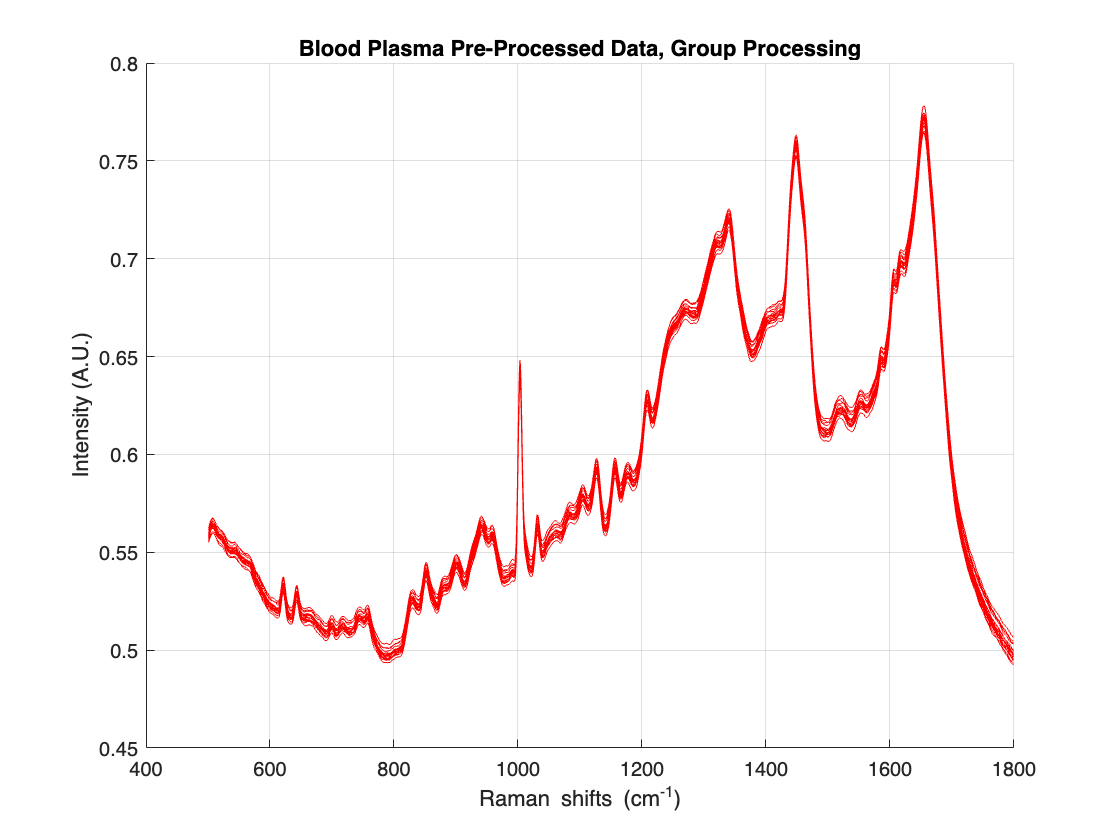

% Preprocessing the data

pro_blood1_1 = apply(blood1_1, [6,1,10,11,8,2,5,6,7]);
pro_blood2_1 = apply(blood2_1, [6,1,10,11,8,2,5,6,7]);
pro_blood3_1 = apply(blood3_1, [6,1,10,11,8,2,5,6,7]);
pro_blood4_1 = apply(blood4_1, [6,1,10,11,8,2,5,6,7]);
pro_blood5_1 = apply(blood5_1, [6,1,10,11,8,2,5,6,7]);
pro_blood6_1 = apply(blood6_1, [6,1,10,11,8,2,5,6,7]);
pro_blood7_1 = apply(blood7_1, [6,1,10,11,8,2,5,6,7]);
pro_blood8_1 = apply(blood8_1, [6,1,10,11,8,2,5,6,7]);
pro_blood9_1 = apply(blood9_1, [6,1,10,11,8,2,5,6,7]);
pro_blood10_1 = apply(blood10_1, [6,1,10,11,8,2,5,6,7]);

% Checking for processing full dataset at once vs individual

blood_1 = [blood1_1;blood2_1;blood3_1;blood4_1;blood5_1;blood6_1;blood7_1;blood8_1;blood9_1;blood10_1];

pro_blood_1 = apply(blood_1, [6,1,10,11,8,2,5,6,7]);


% Plotting pre-processed data

figure;
hold on;
grid on;
plot(wavenumber, pro_blood_1, '-r');
xlabel('Raman shifts (cm^{-1})')
ylabel('Intensity (A.U.)')
title('Blood Plasma Pre-Processed Data, Group Processing');
hold off;

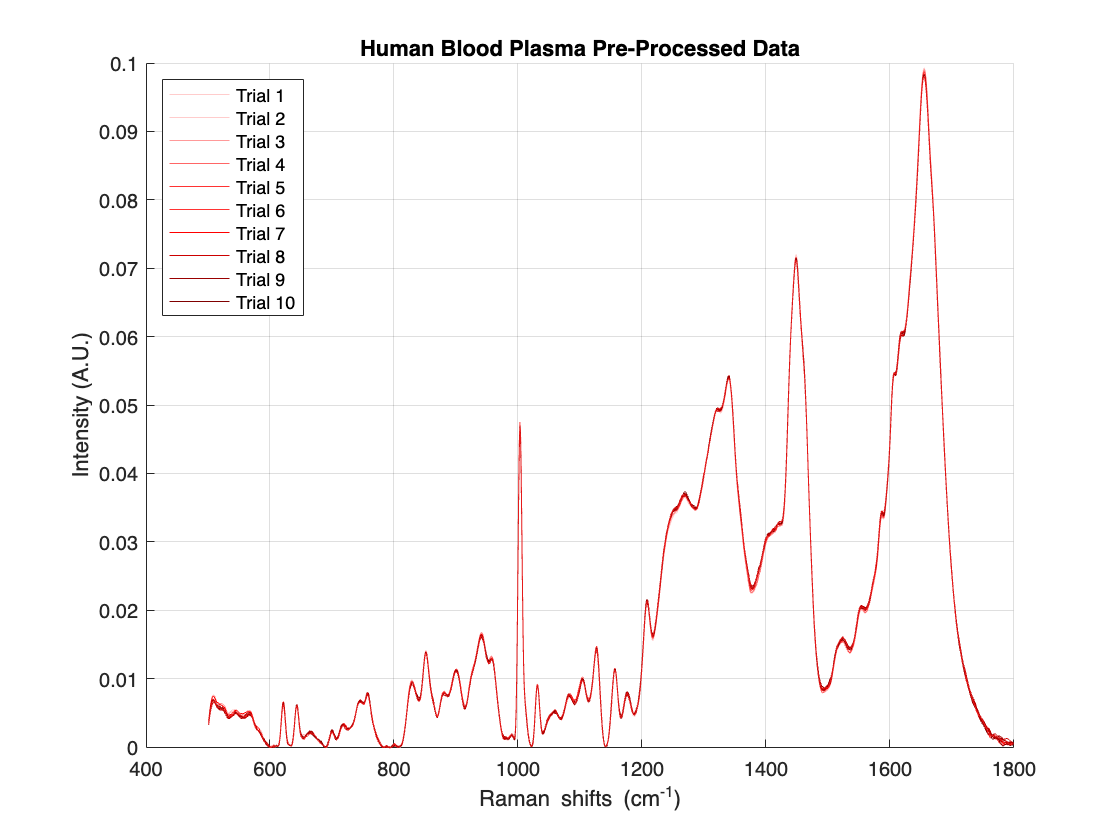

figure;
hold on;
grid on;
plot(wavenumber, pro_blood1_1, 'Color', [1.00, 0.80, 0.80]); % Light Red
plot(wavenumber, pro_blood2_1, 'Color', [1.00, 0.60, 0.60]); % Light Coral
plot(wavenumber, pro_blood3_1, 'Color', [1.00, 0.40, 0.40]); % Salmon
plot(wavenumber, pro_blood4_1, 'Color', [1.00, 0.20, 0.20]); % Indian Red

plot(wavenumber, pro_blood5_1, 'Color', [1.00, 0.00, 0.00]); % Red
plot(wavenumber, pro_blood6_1, 'Color', [0.80, 0.00, 0.00]); % Fire Brick
plot(wavenumber, pro_blood7_1, 'Color', [0.60, 0.00, 0.00]); % Dark Red
plot(wavenumber, pro_blood8_1, 'Color', [0.50, 0.00, 0.00]); % Maroon
plot(wavenumber, pro_blood9_1, 'Color', [0.70, 0.00, 0.00]); % Crimson
plot(wavenumber, pro_blood10_1, 'Color', [0.90, 0.10, 0.10]); % Light Red
xlabel('Raman shifts (cm^{-1})');
ylabel('Intensity (A.U.)');
title('Human Blood Plasma Pre-Processed Data');
legend('Trial 1','Trial 2','Trial 3','Trial 4','Trial 5','Trial 6','Trial 7','Trial 8','Trial 9','Trial 10', 'Location', 'northwest');
hold off;

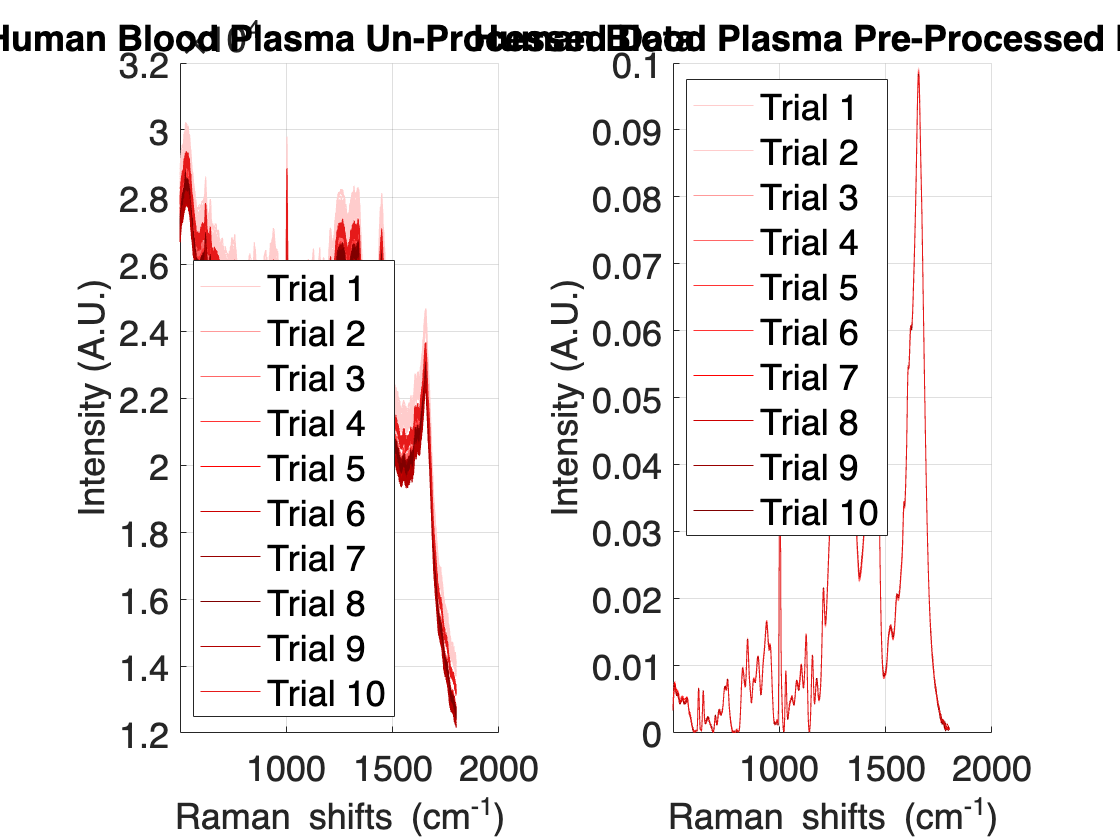

figure;

% First subplot
subplot(1, 2, 1); % 1 row, 2 columns, first subplot
hold on;
grid on;
plot(wavenumber, blood1_1(1,:), 'Color', [1.00, 0.80, 0.80]); % Light Red
plot(wavenumber, blood2_1(1,:), 'Color', [1.00, 0.60, 0.60]); % Light Coral
plot(wavenumber, blood3_1(1,:), 'Color', [1.00, 0.40, 0.40]); % Salmon
plot(wavenumber, blood4_1(1,:), 'Color', [1.00, 0.20, 0.20]); % Indian Red
plot(wavenumber, blood5_1(1,:), 'Color', [1.00, 0.00, 0.00]); % Red
plot(wavenumber, blood6_1(1,:), 'Color', [0.80, 0.00, 0.00]); % Fire Brick
plot(wavenumber, blood7_1(1,:), 'Color', [0.60, 0.00, 0.00]); % Dark Red
plot(wavenumber, blood8_1(1,:), 'Color', [0.50, 0.00, 0.00]); % Maroon
plot(wavenumber, blood9_1(1,:), 'Color', [0.70, 0.00, 0.00]); % Crimson
plot(wavenumber, blood10_1(1,:), 'Color', [0.90, 0.10, 0.10]); % Light Red
plot(wavenumber, blood1_1(2:end,:), 'Color', [1.00, 0.80, 0.80]); % Light Red
plot(wavenumber, blood2_1(2:end,:), 'Color', [1.00, 0.60, 0.60]); % Light Coral
plot(wavenumber, blood3_1(2:end,:), 'Color', [1.00, 0.40, 0.40]); % Salmon
plot(wavenumber, blood4_1(2:end,:), 'Color', [1.00, 0.20, 0.20]); % Indian Red
plot(wavenumber, blood5_1(2:end,:), 'Color', [1.00, 0.00, 0.00]); % Red
plot(wavenumber, blood6_1(2:end,:), 'Color', [0.80, 0.00, 0.00]); % Fire Brick
plot(wavenumber, blood7_1(2:end,:), 'Color', [0.60, 0.00, 0.00]); % Dark Red
plot(wavenumber, blood8_1(2:end,:), 'Color', [0.50, 0.00, 0.00]); % Maroon
plot(wavenumber, blood9_1(2:end,:), 'Color', [0.70, 0.00, 0.00]); % Crimson
plot(wavenumber, blood10_1(2:end,:), 'Color', [0.90, 0.10, 0.10]); % Light Red
xlabel('Raman shifts (cm^{-1})');
ylabel('Intensity (A.U.)');
title('Human Blood Plasma Un-Processed Data');
legend('Trial 1','Trial 2','Trial 3','Trial 4','Trial 5','Trial 6','Trial 7','Trial 8','Trial 9','Trial 10', 'location', 'southwest');
fontsize(18, "points");
hold off;

% Second subplot
subplot(1, 2, 2); % 1 row, 2 columns, second subplot
hold on;
grid on;
plot(wavenumber, pro_blood1_1, 'Color', [1.00, 0.80, 0.80]); % Light Red
plot(wavenumber, pro_blood2_1, 'Color', [1.00, 0.60, 0.60]); % Light Coral
plot(wavenumber, pro_blood3_1, 'Color', [1.00, 0.40, 0.40]); % Salmon
plot(wavenumber, pro_blood4_1, 'Color', [1.00, 0.20, 0.20]); % Indian Red
plot(wavenumber, pro_blood5_1, 'Color', [1.00, 0.00, 0.00]); % Red
plot(wavenumber, pro_blood6_1, 'Color', [0.80, 0.00, 0.00]); % Fire Brick

plot(wavenumber, pro_blood7_1, 'Color', [0.60, 0.00, 0.00]); % Dark Red
plot(wavenumber, pro_blood8_1, 'Color', [0.50, 0.00, 0.00]); % Maroon
plot(wavenumber, pro_blood9_1, 'Color', [0.70, 0.00, 0.00]); % Crimson
plot(wavenumber, pro_blood10_1, 'Color', [0.90, 0.10, 0.10]); % Light Red
xlabel('Raman shifts (cm^{-1})');
ylabel('Intensity (A.U.)');
title('Human Blood Plasma Pre-Processed Data');
legend('Trial 1','Trial 2','Trial 3','Trial 4','Trial 5','Trial 6','Trial 7','Trial 8','Trial 9','Trial 10', 'Location', 'northwest');
fontsize(18, "points");
hold off;

# Well 2 Data

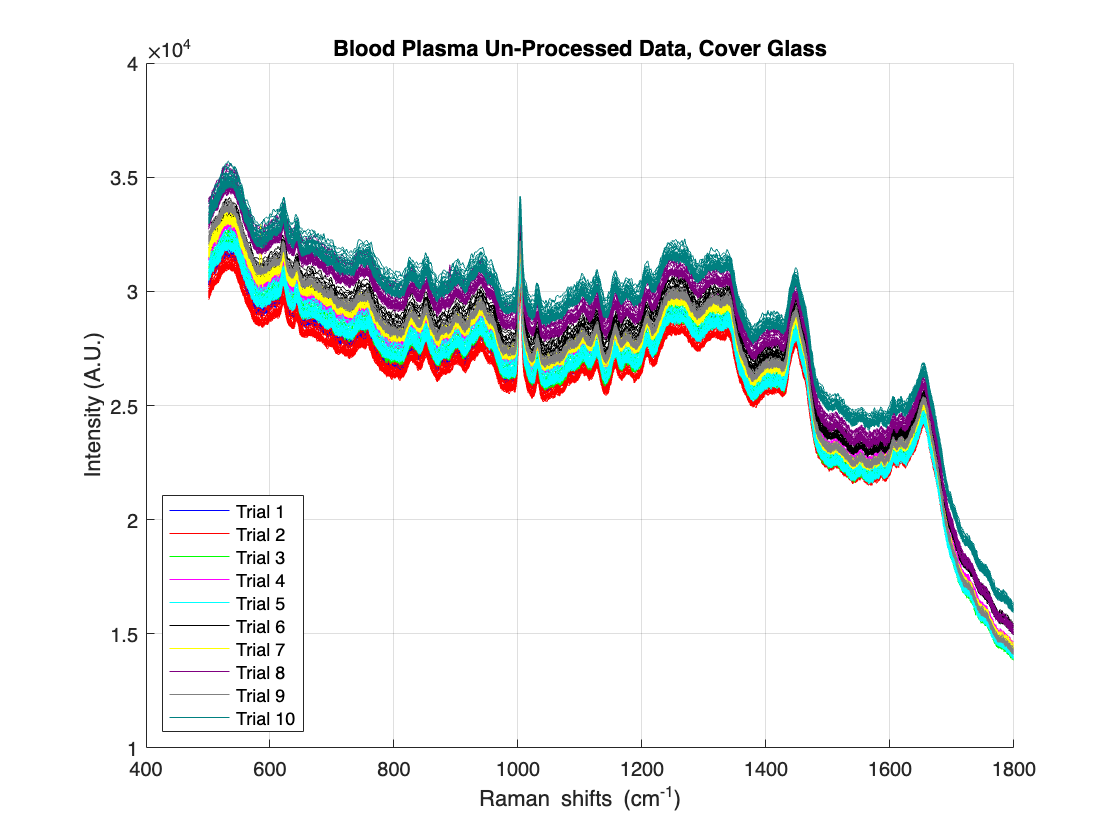

% Plotting unprocessed data

figure;
hold on;
grid on;
plot(wavenumber, blood1_2(1,:), 'Color', [0 0 1]); % Blue
plot(wavenumber, blood2_2(1,:), 'Color', [1 0 0]); % Red
plot(wavenumber, blood3_2(1,:), 'Color', [0 1 0]); % Green
plot(wavenumber, blood4_2(1,:), 'Color', [1 0 1]); % Magenta
plot(wavenumber, blood5_2(1,:), 'Color', [0 1 1]); % Cyan
plot(wavenumber, blood6_2(1,:), 'Color', [0 0 0]); % Black
plot(wavenumber, blood7_2(1,:), 'Color', [1 1 0]); % Yellow
plot(wavenumber, blood8_2(1,:), 'Color', [0.5 0 0.5]); % Purple
plot(wavenumber, blood9_2(1,:), 'Color', [0.5 0.5 0.5]); % Gray
plot(wavenumber, blood10_2(1,:), 'Color', [0 0.5 0.5]); % Teal
plot(wavenumber, blood1_2(2:end,:), 'Color', [0 0 1]); % Blue
plot(wavenumber, blood2_2(2:end,:), 'Color', [1 0 0]); % Red
plot(wavenumber, blood3_2(2:end,:), 'Color', [0 1 0]); % Green
plot(wavenumber, blood4_2(2:end,:), 'Color', [1 0 1]); % Magenta
plot(wavenumber, blood5_2(2:end,:), 'Color', [0 1 1]); % Cyan
plot(wavenumber, blood6_2(2:end,:), 'Color', [0 0 0]); % Black
plot(wavenumber, blood7_2(2:end,:), 'Color', [1 1 0]); % Yellow

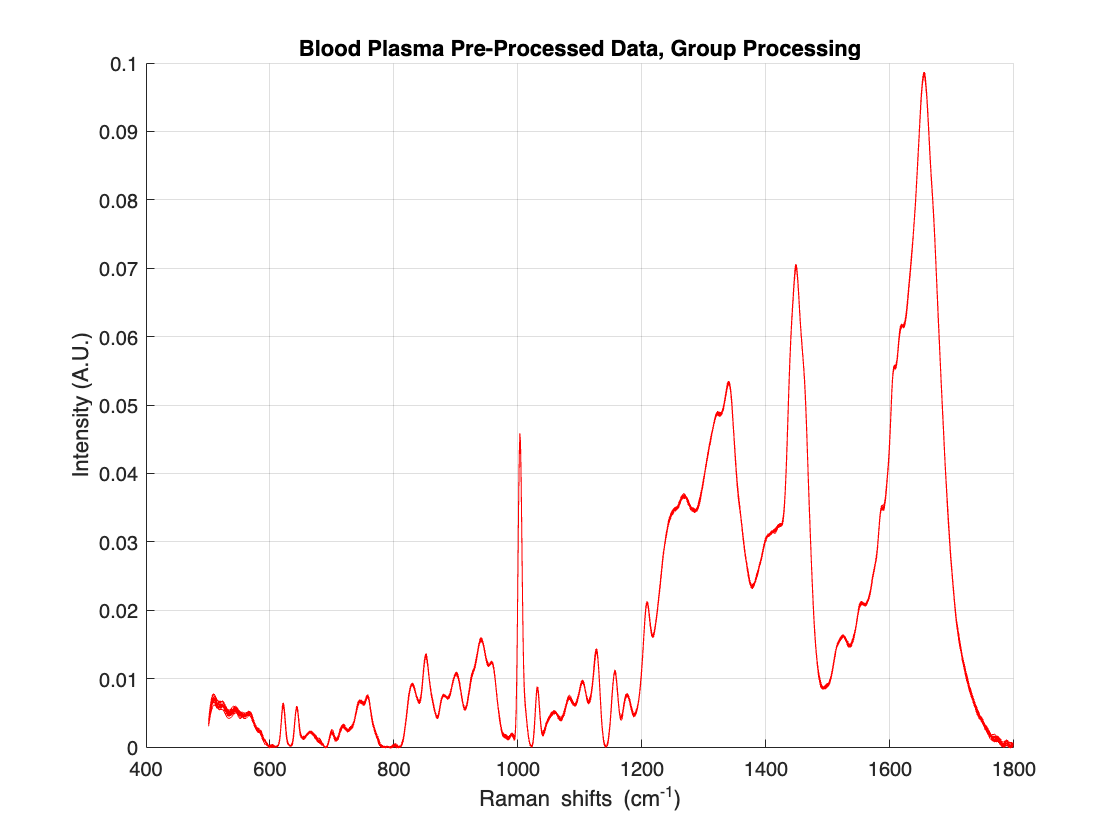

plot(wavenumber, blood8_2(2:end,:), 'Color', [0.5 0 0.5]); % Purple
plot(wavenumber, blood9_2(2:end,:), 'Color', [0.5 0.5 0.5]); % Gray
plot(wavenumber, blood10_2(2:end,:), 'Color', [0 0.5 0.5]); % Teal
xlabel('Raman shifts (cm^{-1})');
ylabel('Intensity (A.U.)');
title('Blood Plasma Un-Processed Data, Cover Glass');
legend('Trial 1','Trial 2','Trial 3','Trial 4','Trial 5','Trial 6','Trial 7','Trial 8','Trial 9','Trial 10', 'location', 'southwest');
hold off;
% Preprocessing the data

pro_blood1_2 = apply(blood1_2, [6,1,10,11,8,2,5,6,7]);
pro_blood2_2 = apply(blood2_2, [6,1,10,11,8,2,5,6,7]);
pro_blood3_2 = apply(blood3_2, [6,1,10,11,8,2,5,6,7]);
pro_blood4_2 = apply(blood4_2, [6,1,10,11,8,2,5,6,7]);
pro_blood5_2 = apply(blood5_2, [6,1,10,11,8,2,5,6,7]);
pro_blood6_2 = apply(blood6_2, [6,1,10,11,8,2,5,6,7]);
pro_blood7_2 = apply(blood7_2, [6,1,10,11,8,2,5,6,7]);
pro_blood8_2 = apply(blood8_2, [6,1,10,11,8,2,5,6,7]);
pro_blood9_2 = apply(blood9_2, [6,1,10,11,8,2,5,6,7]);
pro_blood10_2 = apply(blood10_2, [6,1,10,11,8,2,5,6,7]);

% Checking for processing full dataset at once vs individual

blood_2 = [blood1_2;blood2_2;blood3_2;blood4_2;blood5_2;blood6_2;blood7_2;blood8_2;blood9_2;blood10_2];
pro_blood_2 = apply(blood_2, [6,1,10,11,8,2,5,6,7]);

% Plotting pre-processed data


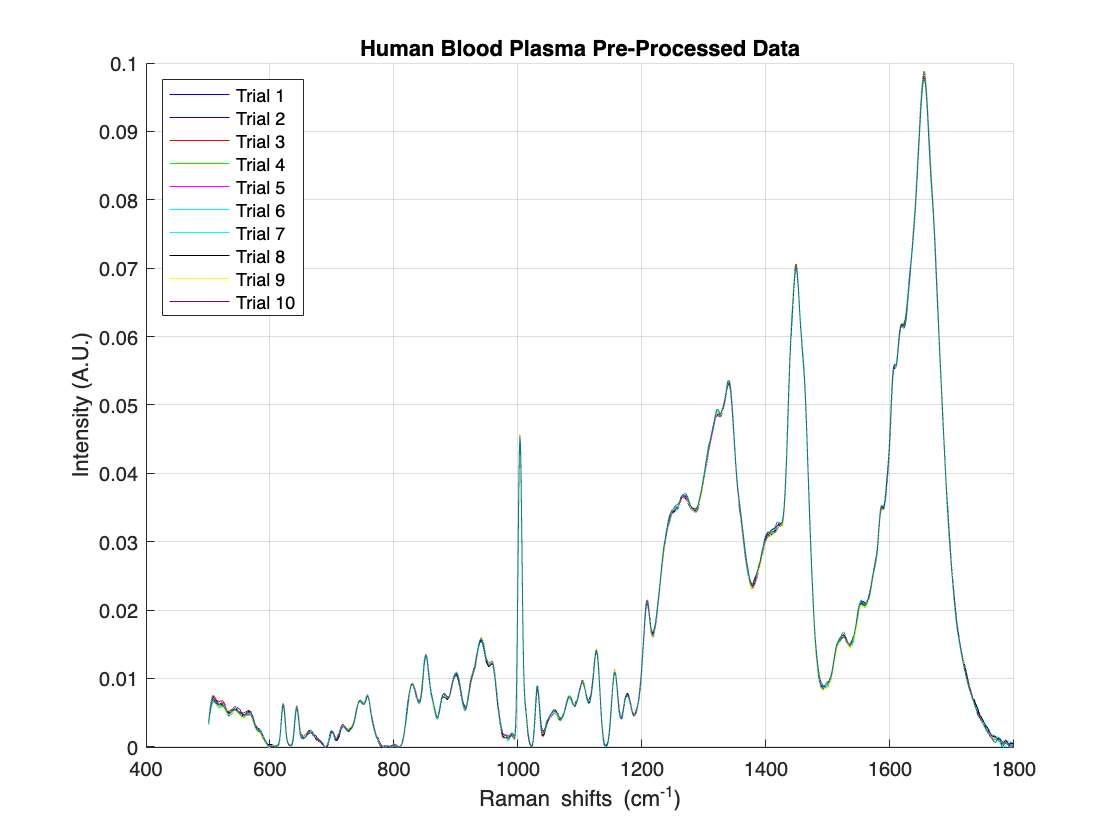

figure;
hold on;
grid on;
plot(wavenumber, pro_blood_2, '-r');
xlabel('Raman shifts (cm^{-1})')
ylabel('Intensity (A.U.)')
title('Blood Plasma Pre-Processed Data, Group Processing');
hold off;
figure;
hold on;
grid on;
plot(wavenumber, pro_blood1_2, 'Color', [0 0 1]); % Blue
plot(wavenumber, pro_blood2_2, 'Color', [1 0 0]); % Red
plot(wavenumber, pro_blood3_2, 'Color', [0 1 0]); % Green
plot(wavenumber, pro_blood4_2, 'Color', [1 0 1]); % Magenta
plot(wavenumber, pro_blood5_2, 'Color', [0 1 1]); % Cyan
plot(wavenumber, pro_blood6_2, 'Color', [0 0 0]); % Black
plot(wavenumber, pro_blood7_2, 'Color', [1 1 0]); % Yellow

plot(wavenumber, pro_blood8_2, 'Color', [0.5 0 0.5]); % Purple
plot(wavenumber, pro_blood9_2, 'Color', [0.5 0.5 0.5]); % Gray
plot(wavenumber, pro_blood10_2, 'Color', [0 0.5 0.5]); % Teal
xlabel('Raman shifts (cm^{-1})');
ylabel('Intensity (A.U.)');
title('Human Blood Plasma Pre-Processed Data');
legend('Trial 1','Trial 2','Trial 3','Trial 4','Trial 5','Trial 6','Trial 7','Trial 8','Trial 9','Trial 10', 'Location', 'northwest');
hold off;

# Well 3 Data

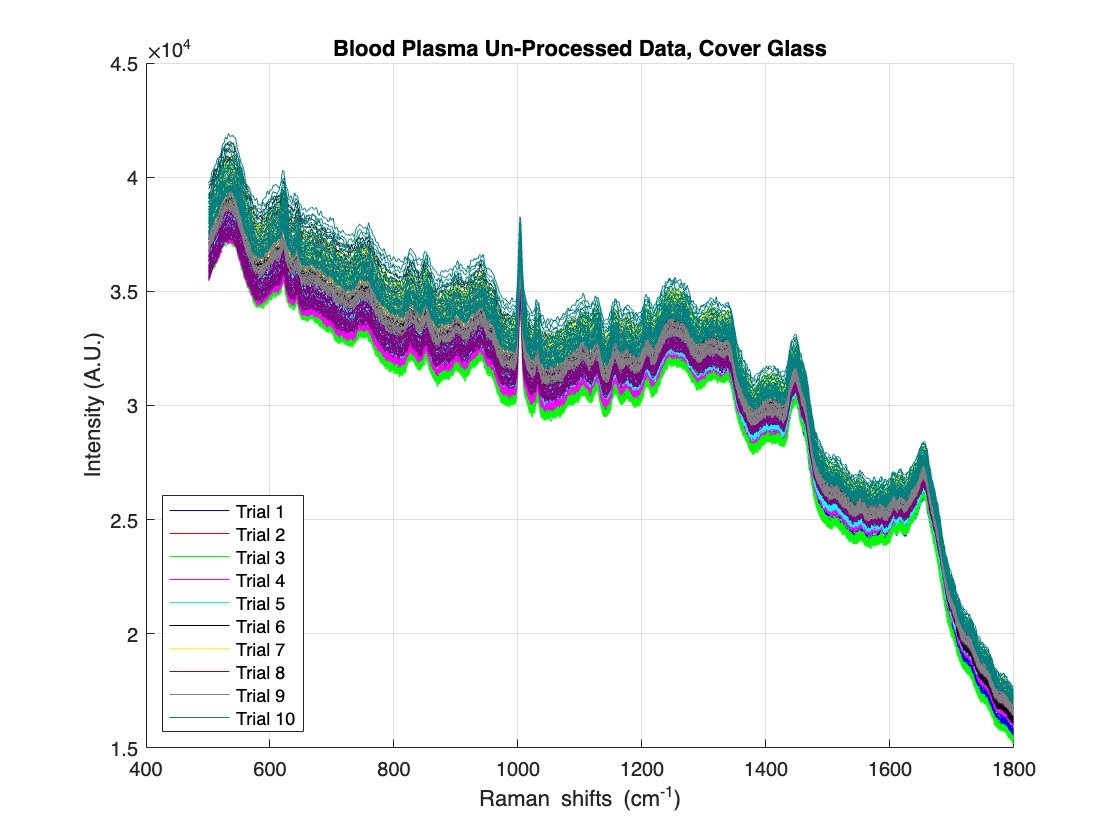

% Plotting unprocessed data

figure;
hold on;
grid on;
plot(wavenumber, blood1_3(1,:), 'Color', [0 0 1]); % Blue
plot(wavenumber, blood2_3(1,:), 'Color', [1 0 0]); % Red
plot(wavenumber, blood3_3(1,:), 'Color', [0 1 0]); % Green
plot(wavenumber, blood4_3(1,:), 'Color', [1 0 1]); % Magenta
plot(wavenumber, blood5_3(1,:), 'Color', [0 1 1]); % Cyan
plot(wavenumber, blood6_3(1,:), 'Color', [0 0 0]); % Black
plot(wavenumber, blood7_3(1,:), 'Color', [1 1 0]); % Yellow
plot(wavenumber, blood8_3(1,:), 'Color', [0.5 0 0.5]); % Purple
plot(wavenumber, blood9_3(1,:), 'Color', [0.5 0.5 0.5]); % Gray
plot(wavenumber, blood10_3(1,:), 'Color', [0 0.5 0.5]); % Teal
plot(wavenumber, blood1_3(2:end,:), 'Color', [0 0 1]); % Blue
plot(wavenumber, blood2_3(2:end,:), 'Color', [1 0 0]); % Red
plot(wavenumber, blood3_3(2:end,:), 'Color', [0 1 0]); % Green
plot(wavenumber, blood4_3(2:end,:), 'Color', [1 0 1]); % Magenta
plot(wavenumber, blood5_3(2:end,:), 'Color', [0 1 1]); % Cyan
plot(wavenumber, blood6_3(2:end,:), 'Color', [0 0 0]); % Black
plot(wavenumber, blood7_3(2:end,:), 'Color', [1 1 0]); % Yellow
plot(wavenumber, blood8_3(2:end,:), 'Color', [0.5 0 0.5]); % Purple
plot(wavenumber, blood9_3(2:end,:), 'Color', [0.5 0.5 0.5]); % Gray

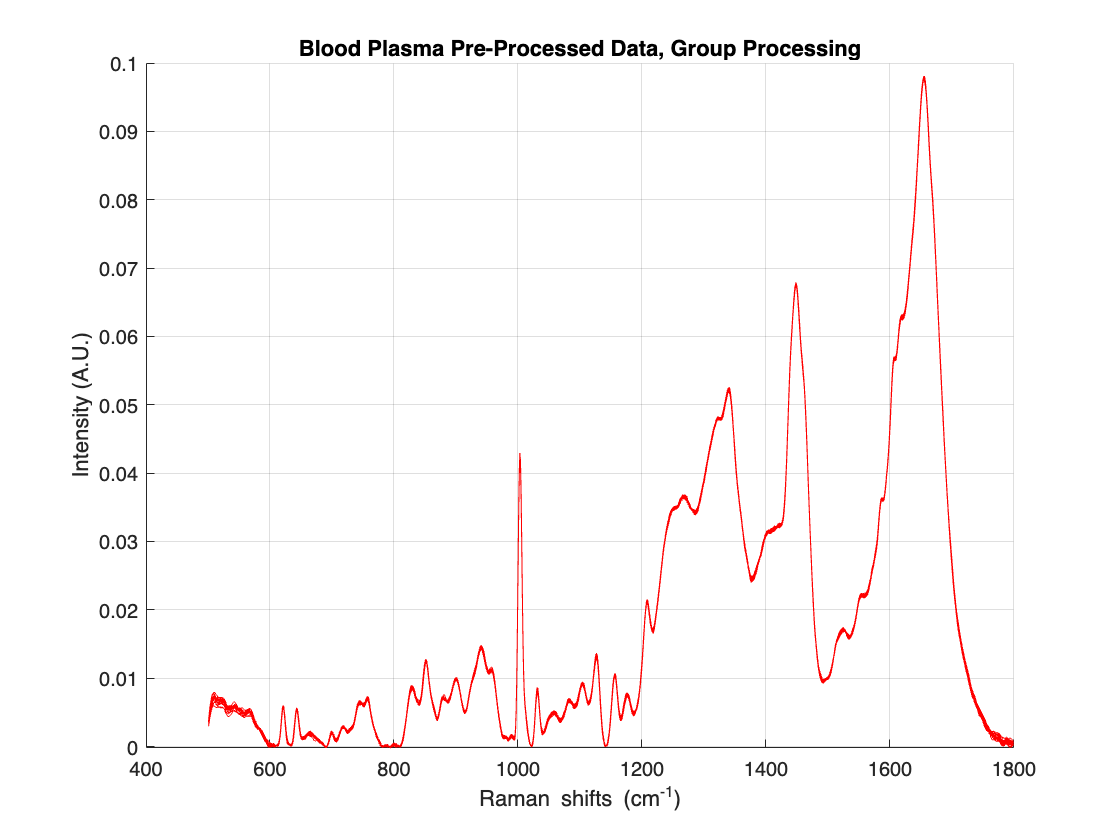

plot(wavenumber, blood10_3(2:end,:), 'Color', [0 0.5 0.5]); % Teal
xlabel('Raman shifts (cm^{-1})');
ylabel('Intensity (A.U.)');
title('Blood Plasma Un-Processed Data, Cover Glass');
legend('Trial 1','Trial 2','Trial 3','Trial 4','Trial 5','Trial 6','Trial 7','Trial 8','Trial 9','Trial 10', 'location', 'southwest');
hold off;
% Preprocessing the data for well 3

pro_blood1_3 = apply(blood1_3, [6,1,10,11,8,2,5,6,7]);
pro_blood2_3 = apply(blood2_3, [6,1,10,11,8,2,5,6,7]);
pro_blood3_3 = apply(blood3_3, [6,1,10,11,8,2,5,6,7]);
pro_blood4_3 = apply(blood4_3, [6,1,10,11,8,2,5,6,7]);
pro_blood5_3 = apply(blood5_3, [6,1,10,11,8,2,5,6,7]);
pro_blood6_3 = apply(blood6_3, [6,1,10,11,8,2,5,6,7]);
pro_blood7_3 = apply(blood7_3, [6,1,10,11,8,2,5,6,7]);
pro_blood8_3 = apply(blood8_3, [6,1,10,11,8,2,5,6,7]);
pro_blood9_3 = apply(blood9_3, [6,1,10,11,8,2,5,6,7]);
pro_blood10_3 = apply(blood10_3, [6,1,10,11,8,2,5,6,7]);

% Checking for processing full dataset at once vs individual

blood_3 = [blood1_3;blood2_3;blood3_3;blood4_3;blood5_3;blood6_3;blood7_3;blood8_3;blood9_3;blood10_3];
pro_blood_3 = apply(blood_3, [6,1,10,11,8,2,5,6,7]);

% Plotting pre-processed data

figure;
hold on;

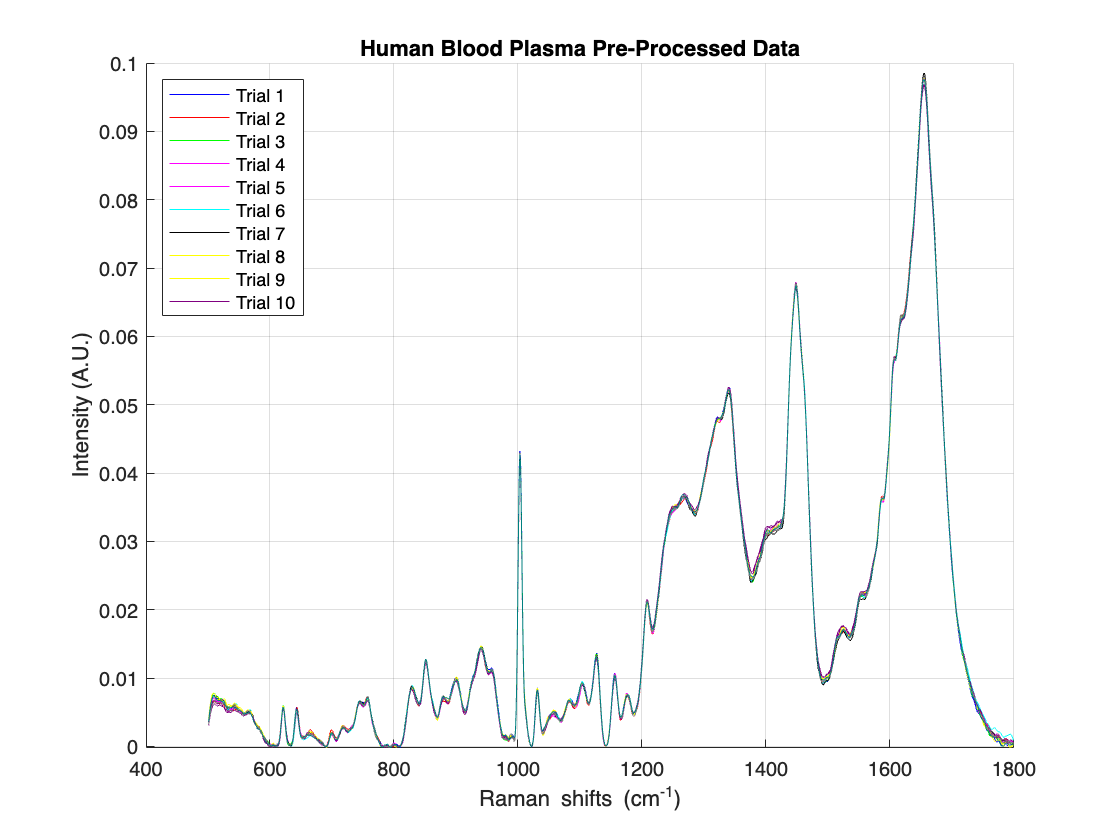

grid on;
plot(wavenumber, pro_blood_3, '-r');
xlabel('Raman shifts (cm^{-1})')
ylabel('Intensity (A.U.)')
title('Blood Plasma Pre-Processed Data, Group Processing');
hold off;
figure;
hold on;
grid on;
plot(wavenumber, pro_blood1_3, 'Color', [0 0 1]); % Blue
plot(wavenumber, pro_blood2_3, 'Color', [1 0 0]); % Red
plot(wavenumber, pro_blood3_3, 'Color', [0 1 0]); % Green
plot(wavenumber, pro_blood4_3, 'Color', [1 0 1]); % Magenta
plot(wavenumber, pro_blood5_3, 'Color', [0 1 1]); % Cyan
plot(wavenumber, pro_blood6_3, 'Color', [0 0 0]); % Black
plot(wavenumber, pro_blood7_3, 'Color', [1 1 0]); % Yellow
plot(wavenumber, pro_blood8_3, 'Color', [0.5 0 0.5]); % Purple
plot(wavenumber, pro_blood9_3, 'Color', [0.5 0.5 0.5]); % Gray

plot(wavenumber, pro_blood10_3, 'Color', [0 0.5 0.5]); % Teal
xlabel('Raman shifts (cm^{-1})');
ylabel('Intensity (A.U.)');
title('Human Blood Plasma Pre-Processed Data');
legend('Trial 1','Trial 2','Trial 3','Trial 4','Trial 5','Trial 6','Trial 7','Trial 8','Trial 9','Trial 10', 'Location', 'northwest');
hold off;

# Well Comparison Plots

- Raw data is shown in the first figure of this section, with red, blue, and green corresponding to well 1, 2 and 3 respectively.

- Processing was performed on the entire dataset for each well, resulting in 3 sets of pre-processed data, shown in red, blue, and green in accordance with the raw data.

- The third plot contains pre-processing of the grouped data, where an array was made containing all data from each well and was subsequently processed using the 'apply' function.

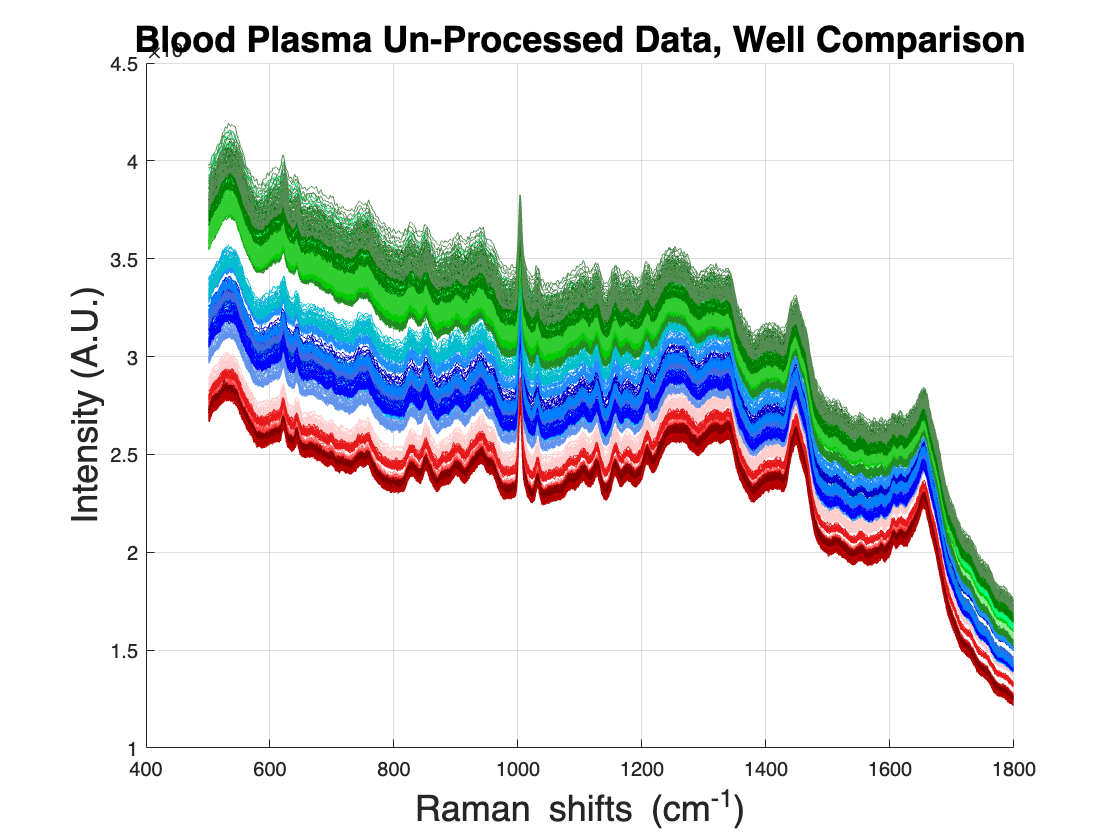

% Comparing raw data

figure;
hold on;
grid on;

% Different shades of red
plot(wavenumber, blood1_1, 'Color', [1.00, 0.80, 0.80]); % Light Red
plot(wavenumber, blood2_1, 'Color', [1.00, 0.60, 0.60]); % Light Coral
plot(wavenumber, blood3_1, 'Color', [1.00, 0.40, 0.40]); % Salmon
plot(wavenumber, blood4_1, 'Color', [1.00, 0.20, 0.20]); % Indian Red
plot(wavenumber, blood5_1, 'Color', [1.00, 0.00, 0.00]); % Red
plot(wavenumber, blood6_1, 'Color', [0.80, 0.00, 0.00]); % Fire Brick
plot(wavenumber, blood7_1, 'Color', [0.60, 0.00, 0.00]); % Dark Red
plot(wavenumber, blood8_1, 'Color', [0.50, 0.00, 0.00]); % Maroon
plot(wavenumber, blood9_1, 'Color', [0.70, 0.00, 0.00]); % Crimson
plot(wavenumber, blood10_1, 'Color', [0.90, 0.10, 0.10]); % Light Red

% Different shades of blue
plot(wavenumber, blood1_2, 'Color', [0.68, 0.85, 0.90]); % Light Blue
plot(wavenumber, blood2_2, 'Color', [0.39, 0.58, 0.93]); % Cornflower Blue
plot(wavenumber, blood3_2, 'Color', [0.00, 0.75, 1.00]); % Deep Sky Blue
plot(wavenumber, blood4_2, 'Color', [0.00, 0.45, 0.74]); % Royal Blue
plot(wavenumber, blood5_2, 'Color', [0.00, 0.00, 1.00]); % Blue
plot(wavenumber, blood6_2, 'Color', [0.00, 0.00, 0.80]); % Navy
plot(wavenumber, blood7_2, 'Color', [0.25, 0.41, 0.88]); % Dodger Blue
plot(wavenumber, blood8_2, 'Color', [0.12, 0.56, 1.00]); % Light Sky Blue
plot(wavenumber, blood9_2, 'Color', [0.00, 0.50, 1.00]); % Blue
plot(wavenumber, blood10_2, 'Color', [0.00, 0.75, 0.80]); % Dark Turquoise

% Different shades of green
plot(wavenumber, blood1_3, 'Color', [0.56, 0.93, 0.56]); % Pale Green
plot(wavenumber, blood2_3, 'Color', [0.00, 1.00, 0.00]); % Lime
plot(wavenumber, blood3_3, 'Color', [0.13, 0.55, 0.13]); % Forest Green
plot(wavenumber, blood4_3, 'Color', [0.00, 0.80, 0.00]); % Green
plot(wavenumber, blood5_3, 'Color', [0.20, 0.80, 0.20]); % Lime Green
plot(wavenumber, blood6_3, 'Color', [0.00, 1.00, 0.50]); % Medium Spring Green
plot(wavenumber, blood7_3, 'Color', [0.00, 0.39, 0.00]); % Dark Green
plot(wavenumber, blood8_3, 'Color', [0.19, 0.80, 0.19]); % Lime Green
plot(wavenumber, blood9_3, 'Color', [0.00, 0.50, 0.00]); % Green
plot(wavenumber, blood10_3, 'Color', [0.33, 0.55, 0.33]); % Medium Sea Green

xlabel('Raman shifts (cm^{-1})', 'FontSize', 18);
ylabel('Intensity (A.U.)', 'FontSize', 18);

title('Blood Plasma Un-Processed Data, Well Comparison', 'FontSize', 18);
hold off;

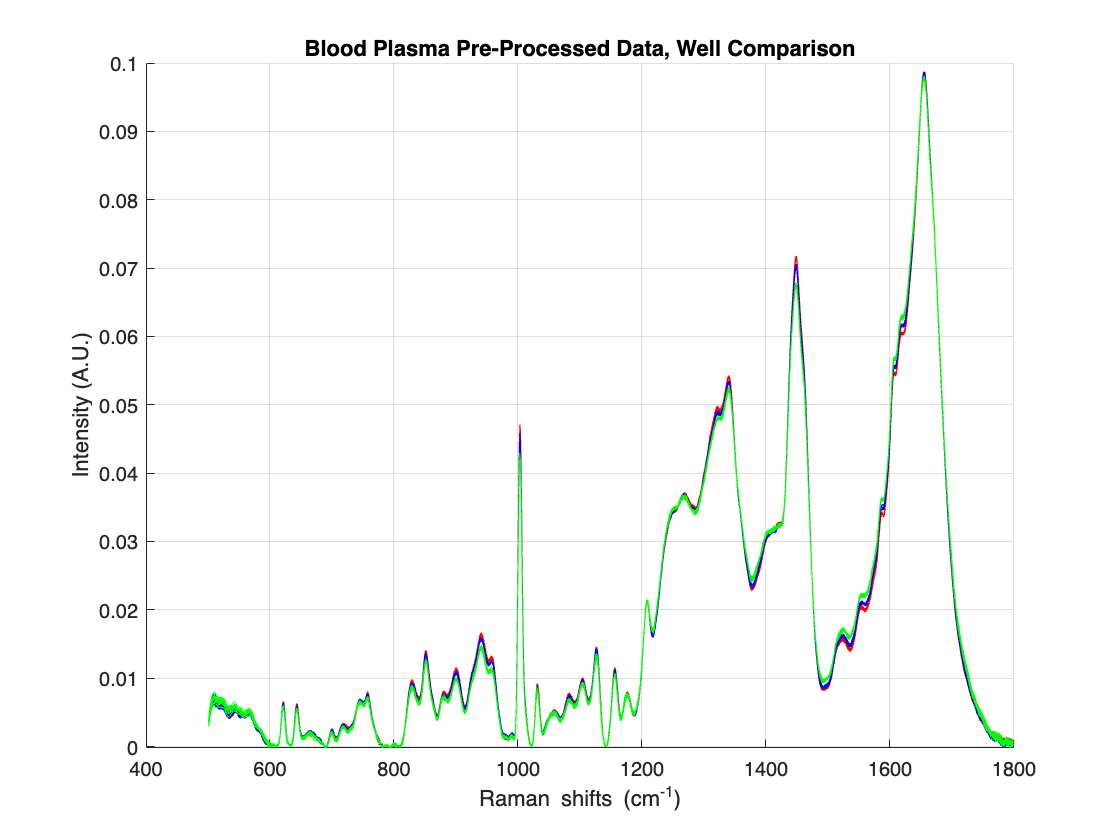

% Comparing group pre-processed data

figure;
hold on;
grid on;
plot(wavenumber, pro_blood_1, '-r');
plot(wavenumber, pro_blood_2, '-b');
plot(wavenumber, pro_blood_3, '-g');
xlabel('Raman shifts (cm^{-1})')
ylabel('Intensity (A.U.)')
title('Blood Plasma Pre-Processed Data, Well Comparison');

hold off;

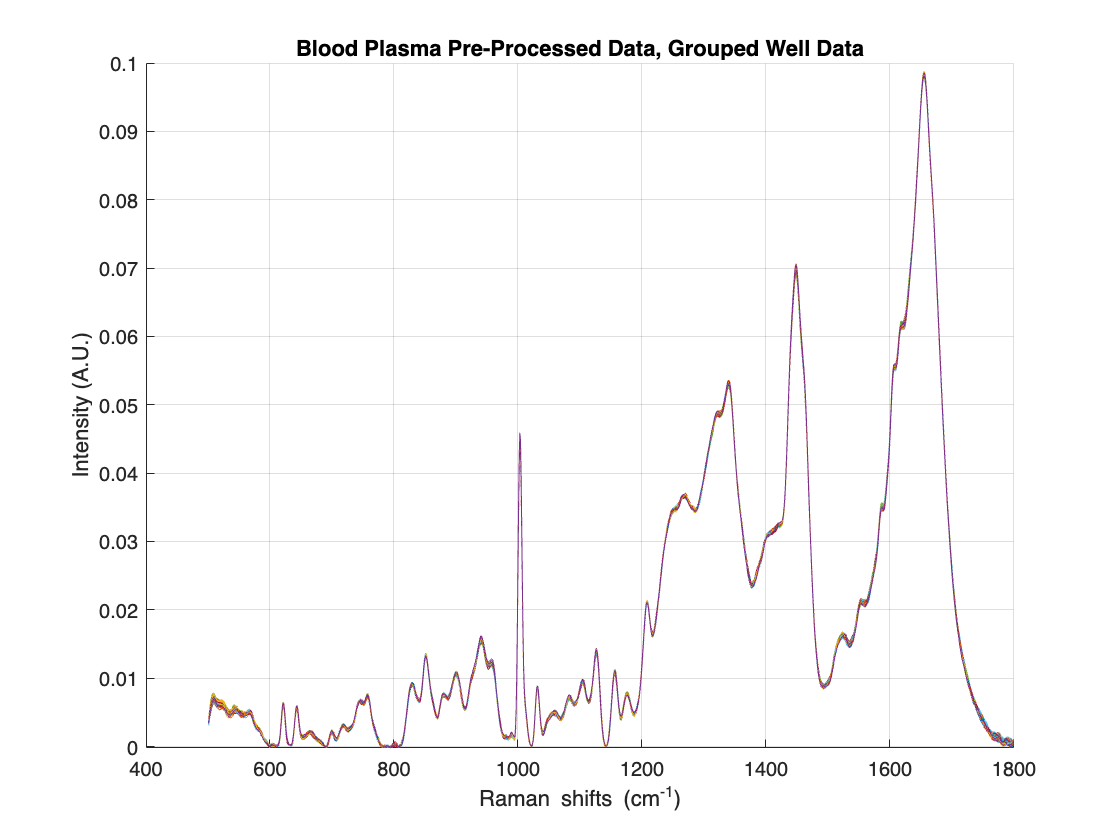

% Performing group processing on all well data

blood = [blood_1;blood_2;blood_3];
pro_blood = apply(blood, [6,1,10,11,8,2,5,6,7]);

figure;
hold on;
grid on;
plot(wavenumber, pro_blood, '-');
xlabel('Raman shifts (cm^{-1})')
ylabel('Intensity (A.U.)')
title('Blood Plasma Pre-Processed Data, Grouped Well Data');
hold off;

signal_1 = mean(pro_blood_1);
noise_1 = mean(blood_1);
snr_1 = snr(signal_1,noise_1)

snr_1 =     -1.186150186376464e+02


function [t_val, p_val, df] = perform_ttest(av1, av2, std1, std2, n1, n2)
    t_val = (av1 - av2) / sqrt((std1^2 / n1) + (std2^2 / n2));
    df = ((std1^2 / n1) + (std2^2 / n2))^2 / ...
         (((std1^2 / n1)^2 / (n1 - 1)) + ((std2^2 / n2)^2 / (n2 - 1)));
    p_val = 2 * (1 - tcdf(abs(t_val), df));
end

function [all, train, test] = prepSet(data, donor, doses, ser, preprocessing)
    all = 0;
    global crnt info
    
    if donor == -1
        donor = unique(data(:,1));
    end

    if doses == -1
        doses = unique(data(:,2))';
        if ismember(999,doses)
            doses = doses(1:end-1);
        end
    end
    
    compiled_to_shuffle = cell(size(doses));
    
    for i = 1:size(donor,2)
        for j = 1:size(doses,2)
            [info, crnt] = dataPicker(data, donor(i), doses(j), ser);

            [crnt, removed] = apply(crnt, preprocessing);
            
            if ismember(8,preprocessing) || ismember(9,preprocessing)
                numRows = ones(size(crnt,1),1);
                info = [donor(i)*numRows doses(j)*numRows 999*numRows];
            else
                for k = 1:size(removed,2)
                    info(removed{k},:) = [];
                end
            end
            
            if all == 0
                all = [info crnt];
            else
                all = [all; info crnt];
            end
            
            if compiled_to_shuffle{j} == 0
                compiled_to_shuffle{j} = [info crnt];
            else
                compiled_to_shuffle{j} = [compiled_to_shuffle{j}; info crnt];
            end
        end
    end
    
    all(:,2) = all(:,2) + 1;
    [train, test] = combine(compiled_to_shuffle);
    train(:,2) = train(:,2) + 1;
    test(:,2) = test(:,2) + 1;
end

function [crnt, removed, corr_shifts] = apply(data, operations)
    global csr sgf MSC SNV bgr bge hqt nrm avg hqr mdn nistcorr NISTspectrum
    
    global avgNum sgfOrder sgfWindow snipOrder snipWindow

    global standardSamples std_int shifts corr_shifts

    global craynum range threshold1 threshold2 remType

    crnt = data;
    
    removed = {};
    
    for i = operations
        if i == 1
            % [crnt, ~, ~, craynum] = remCrays(crnt,1.5,range);
            [crnt, ~, ~, craynum] = CRremove(crnt, threshold1, threshold2, range, remType);
            csr = crnt;
        elseif i == 2
            crnt = sgolayfilt(crnt',sgfOrder,sgfWindow)';
            sgf = crnt;
        elseif i == 3
            [crnt, ~] = msc(crnt);
            MSC = crnt;
        elseif i == 4
            crnt = snv(crnt);
            SNV = crnt;
        elseif i == 5
            [crnt, bge, ~] = bgrem(crnt, snipWindow, 2, 15, snipOrder);
            bgr = crnt;
        elseif i == 6
            [crnt, hqr] = hqTest(crnt);
            removed{1,end+1} = hqr;
            hqt = crnt;
        elseif i == 7
            crnt = normr(crnt);
            nrm = crnt;
        elseif i == 8
            crnt = shuffle(crnt);
            crnt = averager(crnt, avgNum);
            avg = crnt;
        elseif i == 9
            crnt = median(crnt);                                                                    
            mdn = crnt;
       elseif i == 10
            [corr_shifts, crnt] = ramancorrect(shifts, std_int, standardSamples, crnt);
       elseif i == 11
            crnt = nistCorrect(crnt, NISTspectrum, shifts);
            nistcorr = crnt;
        end
    end
end